%Q1)
R0 = 2.5;
numerator = [1,0];
denominator = [1,-R0];
sys = tf(numerator, denominator,1)

sys =
 
     z
  -------
  z - 2.5
 
Sample time: 1 seconds
Discrete-time transfer function.



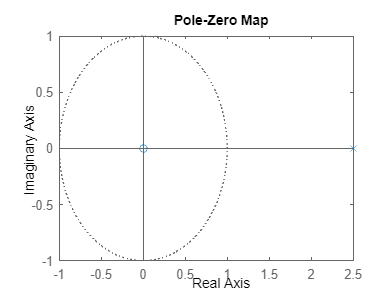

%1
h = pzplot(sys);

%2
ans = log(1000000)/log(R0)

ans = 15.0776

%4
% Covid first wave Mar - Dec 2020
% Ro is estimated at an interval of 30 days in this period  
population = [1 424 1802 7724 19430 55117 82865 86748 45928 32179];
Ro = [0];
for i = population
    Ro(population == i) = 10^(log10(i)/30);
end
Ro_phase1 = mean(Ro) % Ro during first wave

Ro_phase1 = 1.3447

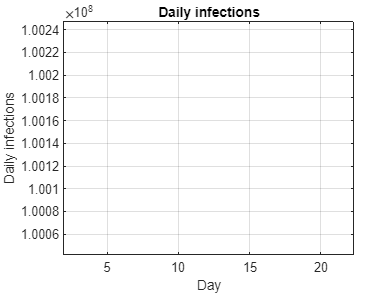

%5
% Parameters
R0 = 2.5;  % Reproduction number
n = 0:1:20;

% Calculate cumulative infections
y = R0.^n;

% Plotting
figure;
stem(n, y, 'b', 'LineWidth', 2);
title('Daily infections');
xlabel('Day');
ylabel('Daily infections');
grid on;

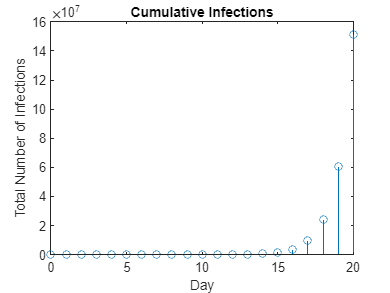

integrator = filter(1, [1,-1], y);
stem(n,integrator)
title('Cumulative Infections');
xlabel('Day');
ylabel('Total Number of Infections')

integrator(21)

ans = 1.5158e+08

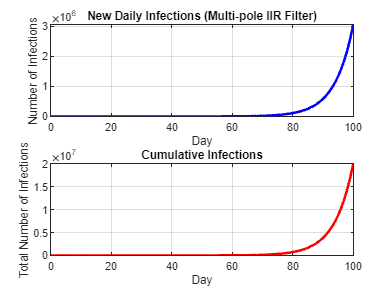

%2)
% Coefficients from Figure 1
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1];  % Virulence coefficients

% Parameters
n_days = 100;  % Number of days

% Define the Kronecker delta input
delta_input = [1, zeros(1, n_days)];  % Kronecker delta at day 0

% Multi-pole IIR filter transfer function
numerator = 1;
denominator = [1, -ak];

daily_infections = filter(numerator,denominator,delta_input);
cumulative_infections = filter(1,[1,-1],daily_infections);

% Plotting
figure;

subplot(2, 1, 1);
plot(0:n_days, daily_infections, 'b', 'LineWidth', 2);
title('New Daily Infections (Multi-pole IIR Filter)');
xlabel('Day');
ylabel('Number of Infections');
grid on;

subplot(2, 1, 2);
plot(0:n_days, cumulative_infections, 'r', 'LineWidth', 2);
title('Cumulative Infections');
xlabel('Day');
ylabel('Total Number of Infections');
grid on;

% Initialize variables
threshold = 1e6;  % Threshold for new daily infections
days_to_threshold = 0;

% Loop to find the day when new daily infections exceed the threshold
for n = 1:length(daily_infections)
    if daily_infections(n) > threshold
        days_to_threshold = n - 1;  % Adjust to start counting from day 0
        break;
    end
end

% Display the result
fprintf('Days to reach 1 million new daily infections: %d days\n', days_to_threshold);

Days to reach 1 million new daily infections: 94 days


fprintf('Total number of infections at 100 days: %d \n', cumulative_infections(n_days+1));

Total number of infections at 100 days: 2.004421e+07 


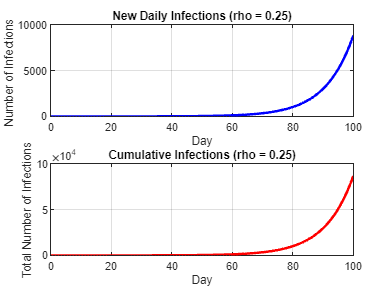

%3)
rho = 0.25;
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1].*(1-rho);  % Virulence coefficients

% Parameters
n_days = 100;  % Number of days

% Define the Kronecker delta input
delta_input = [1, zeros(1, n_days)];  % Kronecker delta at day 0

% Multi-pole IIR filter transfer function
numerator = 1;
denominator = [1, -ak];

daily_infections = filter(numerator,denominator,delta_input);
cumulative_infections = filter(1,[1,-1],daily_infections);

% Plotting
figure;

subplot(2, 1, 1);
plot(0:n_days, daily_infections, 'b', 'LineWidth', 2);
title('New Daily Infections (rho = 0.25)');
xlabel('Day');
ylabel('Number of Infections ');
grid on;

subplot(2, 1, 2);
plot(0:n_days, cumulative_infections, 'r', 'LineWidth', 2);
title('Cumulative Infections (rho = 0.25)');
xlabel('Day');
ylabel('Total Number of Infections');
grid on;

% Initialize variables
threshold = 1e6;  % Threshold for new daily infections
days_to_threshold = 0;

% Loop to find the day when new daily infections exceed the threshold
for n = 1:length(daily_infections)
    if daily_infections(n) > threshold
        days_to_threshold = n - 1;  % Adjust to start counting from day 0
        break;
    end
end

% Display the result
fprintf('Total number of infections at 100 days for rho=0.25: %d \n', cumulative_infections(n_days+1));

Total number of infections at 100 days for rho=0.25: 8.654821e+04 


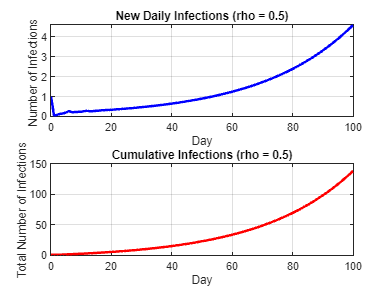

rho = 0.5;
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1].*(1-rho);  % Virulence coefficients

% Parameters
n_days = 100;  % Number of days

% Define the Kronecker delta input
delta_input = [1, zeros(1, n_days)];  % Kronecker delta at day 0

% Multi-pole IIR filter transfer function
numerator = 1;
denominator = [1, -ak];

daily_infections = filter(numerator,denominator,delta_input);
cumulative_infections = filter(1,[1,-1],daily_infections);

% Plotting
figure;

subplot(2, 1, 1);
plot(0:n_days, daily_infections, 'b', 'LineWidth', 2);
title('New Daily Infections (rho = 0.5)');
xlabel('Day');
ylabel('Number of Infections ');
grid on;

subplot(2, 1, 2);
plot(0:n_days, cumulative_infections, 'r', 'LineWidth', 2);
title('Cumulative Infections (rho = 0.5)');
xlabel('Day');
ylabel('Total Number of Infections');
grid on;

% Initialize variables
threshold = 1e6;  % Threshold for new daily infections
days_to_threshold = 0;

% Loop to find the day when new daily infections exceed the threshold
for n = 1:length(daily_infections)
    if daily_infections(n) > threshold
        days_to_threshold = n - 1;  % Adjust to start counting from day 0
        break;
    end
end

% Display the result
fprintf('Total number of infections at 100 days for rho=0.5: %d \n', cumulative_infections(n_days+1));

Total number of infections at 100 days for rho=0.5: 1.385073e+02 


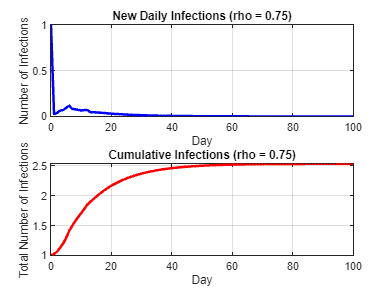

rho = 0.75;
ak = [.1, .15, .25, .26, .34, .42, .25, .2, .15, .1, .1, .1].*(1-rho);  % Virulence coefficients

% Parameters
n_days = 100;  % Number of days

% Define the Kronecker delta input
delta_input = [1, zeros(1, n_days)];  % Kronecker delta at day 0

% Multi-pole IIR filter transfer function
numerator = 1;
denominator = [1, -ak];

daily_infections = filter(numerator,denominator,delta_input);
cumulative_infections = filter(1,[1,-1],daily_infections);

% Plotting
figure;

subplot(2, 1, 1);
plot(0:n_days, daily_infections, 'b', 'LineWidth', 2);
title('New Daily Infections (rho = 0.75)');
xlabel('Day');
ylabel('Number of Infections');
grid on;

subplot(2, 1, 2);
plot(0:n_days, cumulative_infections, 'r', 'LineWidth', 2);
title('Cumulative Infections (rho = 0.75)');
xlabel('Day');
ylabel('Total Number of Infections');
grid on;

% Initialize variables
threshold = 1e6;  % Threshold for new daily infections
days_to_threshold = 0;

% Loop to find the day when new daily infections exceed the threshold
for n = 1:length(daily_infections)
    if daily_infections(n) > threshold
        days_to_threshold = n - 1;  % Adjust to start counting from day 0
        break;
    end
end

% Display the result
fprintf('Total number of infections at 100 days for rho=0.75: %d \n', cumulative_infections(n_days+1));

Total number of infections at 100 days for rho=0.75: 2.531045e+00 


%4)
Ro = 1.15;
K = 10^6;
n = 1:100;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) 

Total_infections2 = 1.6928e+07

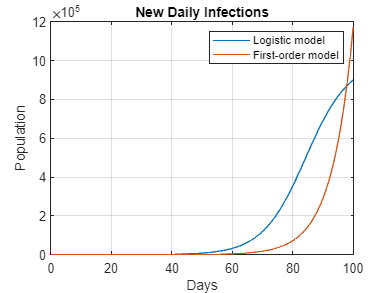


days = 0:100;
Ro = 1.15;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
figure;
plot(n,logistic)
hold on 
plot(days,populationx)
hold off
title("New Daily Infections")
xlabel("Days")
ylabel("Population")
grid on
legend("Logistic model","First-order model")


filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value

Global_maximum = 3.4918e+04

Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value

Value_n = 85

Zero_crossing = n(round(filter_2) == 94) % Inflection point

Zero_crossing = 85